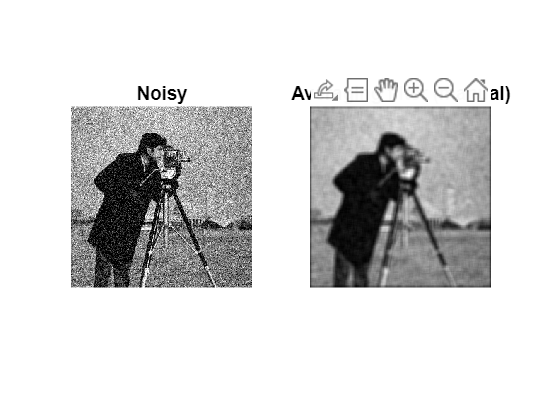

I = im2double(imread('cameraman.tif'));
rng(0)
N = I + 0.15*randn(size(I));
N = min(max(N,0),1);

k = 7;
h = ones(k,k)/(k*k);

p = floor(k/2);
Np = zeros(size(N,1)+2*p,size(N,2)+2*p);
Np(1+p:end-p,1+p:end-p) = N;

Y = zeros(size(N));
for i = 1:size(N,1)
    for j = 1:size(N,2)
        s = 0;
        for u = 1:k
            for v = 1:k
                s = s + h(u,v)*Np(i+u-1,j+v-1);
            end
        end
        Y(i,j) = s;
    end
end

figure('Name','LAB TASK 1');
subplot(1,2,1); imshow(N,[]); title('Noisy');
subplot(1,2,2); imshow(Y,[]); title('Averaging filter (manual)');

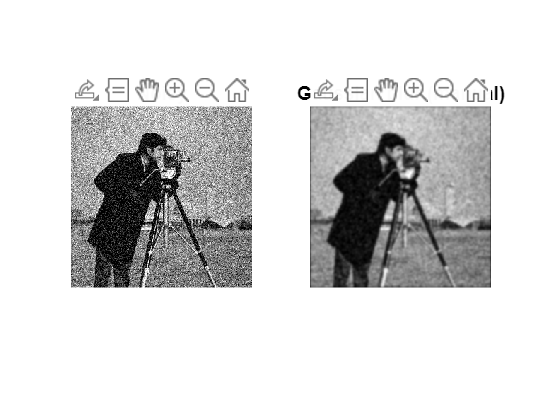


sigma = 1.5;
k = 11;
p = floor(k/2);

g = zeros(k,k);
sumg = 0;
for x = -p:p
    for y = -p:p
        val = exp(-(x*x + y*y)/(2*sigma*sigma));
        g(x+p+1,y+p+1) = val;
        sumg = sumg + val;
    end
end
g = g / sumg;

Np = zeros(size(N,1)+2*p,size(N,2)+2*p);
Np(1+p:end-p,1+p:end-p) = N;

Z = zeros(size(N));
for i = 1:size(N,1)
    for j = 1:size(N,2)
        s = 0;
        for u = 1:k
            for v = 1:k
                s = s + g(u,v)*Np(i+u-1,j+v-1);
            end
        end
        Z(i,j) = s;
    end
end

figure('Name','LAB TASK 2');
subplot(1,2,1); imshow(N,[]); title('Noisy');
subplot(1,2,2); imshow(Z,[]); title('Gaussian blur (manual)');